## MSA model of KUKA_iiwa robot manipulator:

## 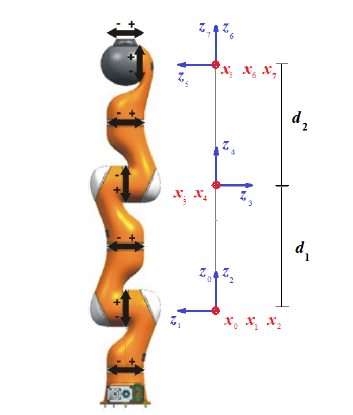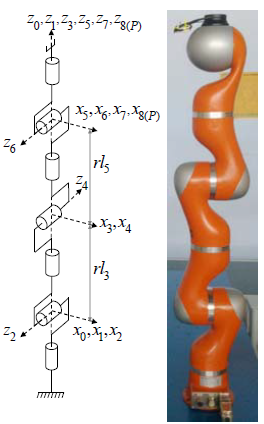

## **Link stiffness model:**


$$
$$ K_{links }= \left[ \begin{array}{cccc}
\begin{array}{cc} K_{11}^{1,2} & K_{12}^{1,2} \\ K_{21}^{1,2} & K_{22}^{1,2} \end{array} & \begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array}& \begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} &\begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} 	  \\
\begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} &  \begin{array}{cc} K_{11}^{23} & K_{12}^{23} \\ K_{21}^{23} & K_{22}^{23} \end{array} &\begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} & \begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} \\
\begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} &\begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} &\begin{array}{cc} .... & .... \\ .... & .... \end{array} & \begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} \\
\begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} & \begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} & \begin{array}{cc} 0 & 0 \\ 0 & 0 \end{array} &  
\begin{array}{cc} K_{11}^{11, 12} & K_{12}^{11, 12} \\ K_{21}^{11, 12} & K_{22}^{11, 12} \end{array}
\end{array} \right]$$$$


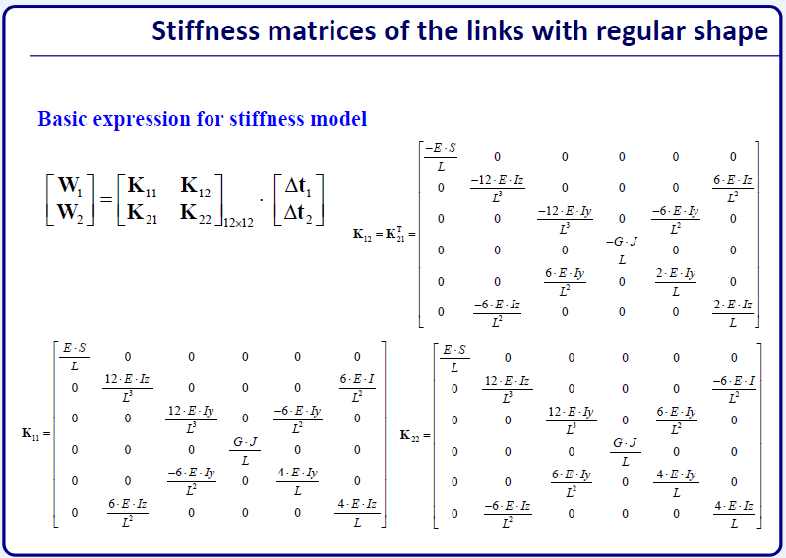

## **For the joints:**

**We have seven elastic joints, three rotations about x, three rotations about z and an elastic support:**

**1. elastic support <0,1>:**


$$$$ \lambda _{*01}^{r} = \left[ \begin{array}{cccccc} 1&0&0&0&0&0 \\ 0&1&0&0&0&0 \\ 0&0&1&0&0&0 \\ 0&0&0&1&0&0 \\ 0&0&0&0&1&0 \end{array} \right]$$
$$
    
$$$$ \lambda _{*01}^{e} = \left[ \begin{array}{cccccc} 0&0&0&0&0&1  \end{array} \right]$$$$



$$
$$ \lambda _{*01}^{r} \cdot \Delta t_{1}= 0_{5\times 1}  \qquad \qquad \qquad 
K_{e} \cdot \lambda _{*01}^{e} \cdot \Delta t_{1} - \lambda _{*01}^{e} \cdot W_{1} = 0 $$ 
$$


**2. elastic joints with rotation about  x-axis  <2,3>**  **<6,7>  <10,11>:**


$$
$$ \lambda _{*ij}^{r} = \left[ \begin{array}{cccccc} 1&0&0&0&0&0 \\ 0&1&0&0&0&0 \\ 0&0&1&0&0&0 \\ 0&0&0&0&1&0 \\ 0&0&0&0&0&1 \end{array} \right]$$

$$
       
$$
$$ \lambda _{*ij}^{e} = \left[ \begin{array}{cccccc} 0&0&0&1&0&0  \end{array} \right]$$
$$
    


$$
$$ \left[ \begin{array}{cccc} \lambda^{e}_{*ij} & 0_{6\times 6} & K^{e}_{ij}\cdot \lambda^{e}_{*ij} &  -K^{e}_{ij}\cdot \lambda^{e}_{*ij}  \\
I_{6\times 6 } & I_{6 \times 6} & 0_{6\times 6} & 0_{6\times 6} \\
0_{6\times 6} & 0_{6\times 6} & \lambda^{r}_{*ij} & -\lambda^{r}_{*ij}   \end{array} \right]
 \left[ \begin{array}{c} W_{i}\\ W_{j} \\ \Delta_{i} \\ \Delta_{j} \end{array} \right] = 
 \left[ \begin{array}{c} 0\\ 0 \\ 0  \end{array} \right] $$$$


**3. elastic joints with rotations about the z-axis ** **<4,5> ** **<8,9>  <12,13>:**


$$
$$ \lambda _{*ij}^{r} = \left[ \begin{array}{cccccc} 1&0&0&0&0&0 \\ 0&1&0&0&0&0 \\ 0&0&1&0&0&0 \\ 0&0&0&1&0&0 \\ 0&0&0&0&1&0 \end{array} \right]$$
$$
     
$$$$ \lambda _{*ij}^{e} = \left[ \begin{array}{cccccc} 0&0&0&0&0&1  \end{array} \right]$$
$$



$$
$$ \left[ \begin{array}{cccc} \lambda^{e}_{*ij} & 0_{6\times 6} & K^{e}_{ij}\cdot \lambda^{e}_{*ij} &  -K^{e}_{ij}\cdot \lambda^{e}_{*ij}  \\
I_{6\times 6 } & I_{6 \times 6} & 0_{6\times 6} & 0_{6\times 6} \\
0_{6\times 6} & 0_{6\times 6} & \lambda^{r}_{*ij} & -\lambda^{r}_{*ij}   \end{array} \right]
 \left[ \begin{array}{c} W_{i}\\ W_{j} \\ \Delta_{i} \\ \Delta_{j} \end{array} \right] = 
 \left[ \begin{array}{c} 0\\ 0 \\ 0  \end{array} \right] $$$$


**4.Aggregated model:**


$$
$$ \left[ \begin{array}{cc} -I_{84\times 84} & K_{links} \\ 0_{35\times 84} & A_{agr} \\ B_{agr}& 0_{36\times 84} \\C_{agr}& D_{agr} \\ E_{agr} & 0_{6\times84} \end{array} \right]
 \left[ \begin{array}{c} W_{agr} \\ \Delta t_{agr}  \end{array} \right] = 
 \left[ \begin{array}{c} 0 _{168 \times 1} \\W_{e} 0  \end{array} \right] $$
$$


     with:       $
$$ A_{agr} = \left[ \begin{array}{ccccccccccccc} \lambda_{*01}^{r} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\ 
0 & \lambda_{*23}^{r} & -\lambda_{*23}^{r} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & \lambda_{*45}^{r} & -\lambda_{*45}^{r} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & \lambda_{*67}^{r} & -\lambda_{*67}^{r} & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & \lambda_{*89}^{r} & -\lambda_{*89}^{r} & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \lambda_{*1011}^{r} & -\lambda_{*1011}^{r} & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \lambda_{*12e}^{r} & -\lambda_{*12e}^{r} \\ \end{array} \right]$$$ $
$$ B_{agr} = \left[ \begin{array}{ccccccccccccc}  
0 & I & I & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & I & I & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & I & I & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & I & I & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & I & I & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & I & I  \end{array} \right]$$$


$$
$$ C_{agr} = \left[ \begin{array}{ccccccccccccc} \lambda_{*01}^{e} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\ 
0 & \lambda_{*23}^{e} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & \lambda_{*45}^{e} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & \lambda_{*67}^{e} & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & \lambda_{*89}^{e} & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \lambda_{*1011}^{e} & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \lambda_{*12e}^{e} & 0 \\ \end{array} \right]$$
$$
 
$$
$$ D_{agr} = \left[ \begin{array}{ccccccccccccc} K_{01}^{e}\cdot\lambda_{*01}^{e} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\ 
0 & K_{23}^{e}\cdot\lambda_{*23}^{e} & -K_{23}^{e}\cdot \lambda_{*23}^{e} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & K_{45}^{e}\cdot \lambda_{*45}^{e} & -K_{45}^{e}\cdot\lambda_{*45}^{e} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & K_{67}^{e}\cdot \lambda_{*67}^{e} & -K_{67}^{e}\cdot\lambda_{*67}^{e} & 0 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & K_{89}^{e}\cdot\lambda_{*89}^{e} & -K_{89}^{e}\cdot\lambda_{*89}^{e} & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & K_{1011}^{e}\cdot\lambda_{*1011}^{e} & -K_{1011}^{e}\cdot\lambda_{*1011}^{e} & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & K_{12e}^{e}\cdot\lambda_{*12e}^{e} & -K_{12e}^{e}\cdot\lambda_{*12e}^{e} \\ \end{array} \right]$$
$$


clear all, clc

robot.Tbase = eye(4);
robot.Ttool = eye(4);
q1 = 0;
q2 = 0;
q3 = 0;
q4 = 0;
q5 = 0;
q6 = 0;
q7 = 0;
% Actuator stiff
robot.Kact=1e6;

% material and shape parameters
E = 70 *10e9; % Young's modulus
G = 25.5*10e9; % shear modulus
d_1 = 10*10e-3;

% we have four type of links corresponding to four lengths
robot.L(1) = 0.21;
robot.L(2) = 0.2;
robot.L(3) = 0.126;
robot.L(4) = 0.05;

% for cylinder
S = pi*d_1^2/4;
Iy = pi*d_1^4/64;
Iz = pi*d_1^4/64;
J = Iy + Iz;

%% links stiffness models
% LINK TYPE 1
robot.k11_1 = [E*S/robot.L(1) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(1)^3  0                 0           0                 6*E*Iz/robot.L(1)^2;
    0           0                  12*E*Iy/robot.L(1)^3 0           -6*E*Iy/robot.L(1)^2 0;
    0           0                  0                 G*J/robot.L(1) 0                 0;
    0           0                  -6*E*Iy/robot.L(1)^2 0           4*E*Iy/robot.L(1)      0;
    0           6*E*Iz/robot.L(1)^2   0                 0           0                 4*E*Iz/robot.L(1)];

robot.k12_1 = [-E*S/robot.L(1) 0                   0                  0            0                 0;
    0            -12*E*Iz/robot.L(1)^3  0                  0            0                 6*E*Iz/robot.L(1)^2;
    0           0                    -12*E*Iy/robot.L(1)^3 0            -6*E*Iy/robot.L(1)^2 0;
    0           0                    0                  -G*J/robot.L(1) 0                 0;
    0           0                    6*E*Iy/robot.L(1)^2   0            2*E*Iy/robot.L(1)      0;
    0           -6*E*Iz/robot.L(1)^2    0                  0            0                 2*E*Iz/robot.L(1)];

robot.k21_1 = [-E*S/robot.L(1) 0                   0                  0            0                 0;
    0            -12*E*Iz/robot.L(1)^3  0                  0            0                 -6*E*Iz/robot.L(1)^2;
    0            0                   -12*E*Iy/robot.L(1)^3 0            6*E*Iy/robot.L(1)^2  0;
    0            0                   0                  -G*J/robot.L(1) 0                 0;
    0            0                   -6*E*Iy/robot.L(1)^2  0            2*E*Iy/robot.L(1)    0;
    0            6*E*Iz/robot.L(1)^2    0                  0            0                 2*E*Iz/robot.L(1)];

robot.k22_1 = [E*S/robot.L(1) 0                   0                 0            0                 0;
    0           12*E*Iz/robot.L(1)^3   0                 0            0                 -6*E*Iz/robot.L(1)^2;
    0           0                   12*E*Iy/robot.L(1)^3 0            6*E*Iy/robot.L(1)^2  0;
    0           0                   0                 G*J/robot.L(1)  0                 0;
    0           0                   6*E*Iy/robot.L(1)^2  0            4*E*Iy/robot.L(1)    0;
    0           -6*E*Iz/robot.L(1)^2   0                 0            0                 4*E*Iz/robot.L(1)];


% LINK TYPE 2
robot.k11_2 = [E*S/robot.L(2) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(2)^3  0                 0           0                 6*E*Iz/robot.L(2)^2;
    0           0                  12*E*Iy/robot.L(2)^3 0           -6*E*Iy/robot.L(2)^2 0;
    0           0                  0                 G*J/robot.L(2) 0                 0;
    0           0                  -6*E*Iy/robot.L(2)^2 0           4*E*Iy/robot.L(2)      0;
    0           6*E*Iz/robot.L(2)^2   0                 0           0                 4*E*Iz/robot.L(2)];

robot.k12_2 = [-E*S/robot.L(2) 0                   0                  0            0                 0;
    0            -12*E*Iz/robot.L(2)^3  0                  0            0                 6*E*Iz/robot.L(2)^2;
    0           0                    -12*E*Iy/robot.L(2)^3 0            -6*E*Iy/robot.L(2)^2 0;
    0           0                    0                  -G*J/robot.L(2) 0                 0;
    0           0                    6*E*Iy/robot.L(2)^2   0            2*E*Iy/robot.L(2)      0;
    0           -6*E*Iz/robot.L(2)^2    0                  0            0                 2*E*Iz/robot.L(2)];

robot.k21_2 = [-E*S/robot.L(2) 0                   0                  0            0                 0;
    0            -12*E*Iz/robot.L(2)^3  0                  0            0                 -6*E*Iz/robot.L(2)^2;
    0            0                   -12*E*Iy/robot.L(2)^3 0            6*E*Iy/robot.L(2)^2  0;
    0            0                   0                  -G*J/robot.L(2) 0                 0;
    0            0                   -6*E*Iy/robot.L(2)^2  0            2*E*Iy/robot.L(2)    0;
    0            6*E*Iz/robot.L(2)^2    0                  0            0                 2*E*Iz/robot.L(2)];

robot.k22_2 = [E*S/robot.L(2) 0                   0                 0            0                 0;
    0           12*E*Iz/robot.L(2)^3   0                 0            0                 -6*E*Iz/robot.L(2)^2;
    0           0                   12*E*Iy/robot.L(2)^3 0            6*E*Iy/robot.L(2)^2  0;
    0           0                   0                 G*J/robot.L(2)  0                 0;
    0           0                   6*E*Iy/robot.L(2)^2  0            4*E*Iy/robot.L(2)    0;
    0           -6*E*Iz/robot.L(2)^2   0                 0            0                 4*E*Iz/robot.L(2)];

% LINK TYPE 3
robot.k11_3 = [E*S/robot.L(3) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(3)^3  0                 0           0                 6*E*Iz/robot.L(3)^2;
    0           0                  12*E*Iy/robot.L(3)^3 0           -6*E*Iy/robot.L(3)^2 0;
    0           0                  0                 G*J/robot.L(3) 0                 0;
    0           0                  -6*E*Iy/robot.L(3)^2 0           4*E*Iy/robot.L(3)      0;
    0           6*E*Iz/robot.L(3)^2   0                 0           0                 4*E*Iz/robot.L(3)];

robot.k12_3 = [-E*S/robot.L(3) 0                   0                  0            0                 0;
    0            -12*E*Iz/robot.L(3)^3  0                  0            0                 6*E*Iz/robot.L(3)^2;
    0           0                    -12*E*Iy/robot.L(3)^3 0            -6*E*Iy/robot.L(3)^2 0;
    0           0                    0                  -G*J/robot.L(3) 0                 0;
    0           0                    6*E*Iy/robot.L(3)^2   0            2*E*Iy/robot.L(3)      0;
    0           -6*E*Iz/robot.L(3)^2    0                  0            0                 2*E*Iz/robot.L(3)];

robot.k21_3 = [-E*S/robot.L(3) 0                   0                  0            0                 0;
    0            -12*E*Iz/robot.L(3)^3  0                  0            0                 -6*E*Iz/robot.L(3)^2;
    0            0                   -12*E*Iy/robot.L(3)^3 0            6*E*Iy/robot.L(3)^2  0;
    0            0                   0                  -G*J/robot.L(3) 0                 0;
    0            0                   -6*E*Iy/robot.L(3)^2  0            2*E*Iy/robot.L(3)    0;
    0            6*E*Iz/robot.L(3)^2    0                  0            0                 2*E*Iz/robot.L(3)];

robot.k22_3 = [E*S/robot.L(3) 0                   0                 0            0                 0;
    0           12*E*Iz/robot.L(3)^3   0                 0            0                 -6*E*Iz/robot.L(3)^2;
    0           0                   12*E*Iy/robot.L(3)^3 0            6*E*Iy/robot.L(3)^2  0;
    0           0                   0                 G*J/robot.L(3)  0                 0;
    0           0                   6*E*Iy/robot.L(3)^2  0            4*E*Iy/robot.L(3)    0;
    0           -6*E*Iz/robot.L(3)^2   0                 0            0                 4*E*Iz/robot.L(3)];

% LINK TYPE 4
robot.k11_4 = [E*S/robot.L(4) 0                  0                 0           0                 0;
    0           12*E*Iz/robot.L(4)^3  0                 0           0                 6*E*Iz/robot.L(4)^2;
    0           0                  12*E*Iy/robot.L(4)^3 0           -6*E*Iy/robot.L(4)^2 0;
    0           0                  0                 G*J/robot.L(4) 0                 0;
    0           0                  -6*E*Iy/robot.L(4)^2 0           4*E*Iy/robot.L(4)      0;
    0           6*E*Iz/robot.L(4)^2   0                 0           0                 4*E*Iz/robot.L(4)];

robot.k12_4 = [-E*S/robot.L(4) 0                   0                  0            0                 0;
    0            -12*E*Iz/robot.L(4)^3  0                  0            0                 6*E*Iz/robot.L(4)^2;
    0           0                    -12*E*Iy/robot.L(4)^3 0            -6*E*Iy/robot.L(4)^2 0;
    0           0                    0                  -G*J/robot.L(4) 0                 0;
    0           0                    6*E*Iy/robot.L(4)^2   0            2*E*Iy/robot.L(4)      0;
    0           -6*E*Iz/robot.L(4)^2    0                  0            0                 2*E*Iz/robot.L(4)];

robot.k21_4 = [-E*S/robot.L(4) 0                   0                  0            0                 0;
    0            -12*E*Iz/robot.L(4)^3  0                  0            0                 -6*E*Iz/robot.L(4)^2;
    0            0                   -12*E*Iy/robot.L(4)^3 0            6*E*Iy/robot.L(4)^2  0;
    0            0                   0                  -G*J/robot.L(4) 0                 0;
    0            0                   -6*E*Iy/robot.L(4)^2  0            2*E*Iy/robot.L(4)    0;
    0            6*E*Iz/robot.L(4)^2    0                  0            0                 2*E*Iz/robot.L(4)];

robot.k22_4 = [E*S/robot.L(4) 0                   0                 0            0                 0;
    0           12*E*Iz/robot.L(4)^3   0                 0            0                 -6*E*Iz/robot.L(4)^2;
    0           0                   12*E*Iy/robot.L(4)^3 0            6*E*Iy/robot.L(4)^2  0;
    0           0                   0                 G*J/robot.L(4)  0                 0;
    0           0                   6*E*Iy/robot.L(4)^2  0            4*E*Iy/robot.L(4)    0;
    0           -6*E*Iz/robot.L(4)^2   0                 0            0                 4*E*Iz/robot.L(4)];

%% rotation matrices for K_global
theta = q1;
Rl1= [cos(theta) -sin(theta) 0 0 0 0;
    sin(theta) cos(theta) 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 cos(theta) -sin(theta) 0;
    0 0 0 sin(theta) cos(theta) 0;
    0 0 0 0 0 1];

theta = q2;
Rl2 = Rl1*[1 0 0 0 0 0;
    0 cos(theta) -sin(theta) 0 0 0;
    0 sin(theta) cos(theta) 0 0 0;
    0 0 0 1 0 0;
    0 0 0 0 cos(theta) -sin(theta);
    0 0 0 0 sin(theta) cos(theta)];

theta = q3;
Rl3= Rl2*[cos(theta) -sin(theta) 0 0 0 0;
    sin(theta) cos(theta) 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 cos(theta) -sin(theta) 0;
    0 0 0 sin(theta) cos(theta) 0;
    0 0 0 0 0 1];

theta = q4;
Rl4 = Rl3*[1 0 0 0 0 0;
    0 cos(theta) -sin(theta) 0 0 0;
    0 sin(theta) cos(theta) 0 0 0;
    0 0 0 1 0 0;
    0 0 0 0 cos(theta) -sin(theta);
    0 0 0 0 sin(theta) cos(theta)];

theta = q5;
Rl5= Rl4*[cos(theta) -sin(theta) 0 0 0 0;
    sin(theta) cos(theta) 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 cos(theta) -sin(theta) 0;
    0 0 0 sin(theta) cos(theta) 0;
    0 0 0 0 0 1];

theta = q6;
Rl6 = Rl5*[1 0 0 0 0 0;
    0 cos(theta) -sin(theta) 0 0 0;
    0 sin(theta) cos(theta) 0 0 0;
    0 0 0 1 0 0;
    0 0 0 0 cos(theta) -sin(theta);
    0 0 0 0 sin(theta) cos(theta)];

theta = q7;
Rl7= Rl6*[cos(theta) -sin(theta) 0 0 0 0;
    sin(theta) cos(theta) 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 cos(theta) -sin(theta) 0;
    0 0 0 sin(theta) cos(theta) 0;
    0 0 0 0 0 1];

%% global stiffness parameters
k11_12 = Rl1 * robot.k11_1 * Rl1';
k12_12 = Rl1 * robot.k12_1 * Rl1';
k21_12 = Rl1 * robot.k21_1 * Rl1';
k22_12 = Rl1 * robot.k22_1 * Rl1';

k11_34 = Rl2 * robot.k11_1 * Rl2';
k12_34 = Rl2 * robot.k12_1 * Rl2';
k21_34 = Rl2 * robot.k21_1 * Rl2';
k22_34 = Rl2 * robot.k22_1 * Rl2';

k11_56 = Rl3 * robot.k11_1 * Rl3';
k12_56 = Rl3 * robot.k12_1 * Rl3';
k21_56 = Rl3 * robot.k21_1 * Rl3';
k22_56 = Rl3 * robot.k22_1 * Rl3';

k11_78 = Rl4 * robot.k11_2 * Rl4';
k12_78 = Rl4 * robot.k12_2 * Rl4';
k21_78 = Rl4 * robot.k21_2 * Rl4';
k22_78 = Rl4 * robot.k22_2 * Rl4';

k11_910 = Rl5 * robot.k11_2 * Rl5';
k12_910 = Rl5 * robot.k12_2 * Rl5';
k21_910 = Rl5 * robot.k21_2 * Rl5';
k22_910 = Rl5 * robot.k22_2 * Rl5';

k11_1112 = Rl6 * robot.k11_3 * Rl6';
k12_1112 = Rl6 * robot.k12_3 * Rl6';
k21_1112 = Rl6 * robot.k21_3 * Rl6';
k22_1112 = Rl6 * robot.k22_3 * Rl6';

k11_13e = Rl7 * robot.k11_4 * Rl7';
k12_13e = Rl7 * robot.k12_4 * Rl7';
k21_13e = Rl7 * robot.k21_4 * Rl7';
k22_13e = Rl7 * robot.k22_4 * Rl7';

%% Klink global
Klinks = [k11_12 k12_12 zeros(6,72);
        k21_12 k22_12 zeros(6,72);
        zeros(6,12) k11_34 k12_34 zeros(6,60);
        zeros(6,12) k21_34 k22_34 zeros(6,60);
        zeros(6,24) k11_56 k12_56 zeros(6,48);
        zeros(6,24) k21_56 k22_56 zeros(6,48);
        zeros(6,36) k11_78 k12_78 zeros(6,36);
        zeros(6,36) k21_78 k22_78 zeros(6,36);
        zeros(6,48) k11_910 k12_910 zeros(6,24);
        zeros(6,48) k21_910 k22_910 zeros(6,24);
        zeros(6,60) k11_1112 k12_1112 zeros(6,12);
        zeros(6,60) k21_1112 k22_1112 zeros(6,12)
        zeros(6,72) k11_13e k12_13e;
        zeros(6,72) k21_13e k22_13e];
      
%% joints constraints
Lr01 = [1 0 0 0 0 0;
        0 1 0 0 0 0;
        0 0 1 0 0 0;
        0 0 0 1 0 0;
        0 0 0 0 1 0];
Le01 = [0 0 0 0 0 1];
    
Lr23 = [1 0 0 0 0 0;
        0 1 0 0 0 0;
        0 0 1 0 0 0;
        0 0 0 0 1 0;
        0 0 0 0 0 1];
Le23 = [0 0 0 1 0 0];

%% aggregated matrices
Aagr = [Lr01 zeros(5,72) zeros(5,6);
        zeros(5,6) Lr23 -Lr23 zeros(5,60) zeros(5,6);
        zeros(5,18) Lr01 -Lr01 zeros(5,48) zeros(5,6);
        zeros(5,30) Lr23 -Lr23 zeros(5,36) zeros(5,6);
        zeros(5,42) Lr01 -Lr01 zeros(5,24) zeros(5,6);
        zeros(5,54) Lr23 -Lr23 zeros(5,12) zeros(5,6);
        zeros(5,66) Lr01 -Lr01 zeros(5,6)];
    
Bagr = [zeros(6,6) eye(6) eye(6) zeros(6,60) zeros(6,6);
        zeros(6,18) eye(6) eye(6) zeros(6,48) zeros(6,6);
        zeros(6,30) eye(6) eye(6) zeros(6,36) zeros(6,6);
        zeros(6,42) eye(6) eye(6) zeros(6,24) zeros(6,6);
        zeros(6,54) eye(6) eye(6) zeros(6,12) zeros(6,6);
        zeros(6,66) eye(6) eye(6) zeros(6,6)];

Cagr = [Le01 zeros(1,72) zeros(1,6);
        zeros(1,12) Le23 zeros(1,60) zeros(1,6);
        zeros(1,24) Le01 zeros(1,48) zeros(1,6);
        zeros(1,36) Le23 zeros(1,36) zeros(1,6);
        zeros(1,48) Le01 zeros(1,24) zeros(1,6);
        zeros(1,60) Le23 zeros(1,12) zeros(1,6);
        zeros(1,72) Le01 zeros(1,6)];
        
Dagr = [robot.Kact*Le01 zeros(1,72) zeros(1,6);
        zeros(1,6) robot.Kact*Le23 -robot.Kact*Le23 zeros(1,60) zeros(1,6);
        zeros(1,18) robot.Kact*Le01 -robot.Kact*Le01 zeros(1,48) zeros(1,6);
        zeros(1,30) robot.Kact*Le23 -robot.Kact*Le23 zeros(1,36) zeros(1,6);
        zeros(1,42) robot.Kact*Le01 -robot.Kact*Le01 zeros(1,24) zeros(1,6);
        zeros(1,54) robot.Kact*Le23 -robot.Kact*Le23 zeros(1,12) zeros(1,6);
        zeros(1,66) robot.Kact*Le01 -robot.Kact*Le01 zeros(1,6)];

Eagr = [zeros(6,78) eye(6)];
Fagr = [zeros(6,84)];

Sagr = [-eye(84);zeros(35,84);Bagr;Cagr];
Kagr = [Klinks;Aagr;zeros(36,84);Dagr];

fm=[Sagr Kagr;
    Eagr Fagr];
    
A = fm(1:162,1:162);
B = fm(1:162,163:168);
C = fm(163:168,1:162);
D = fm(163:168,163:168);

% Final formula for Kc
Kc = D - C*inv(A)*B

Kc =    1.0e+07 *

    4.5587         0         0         0         0         0
         0    0.0002         0         0         0   -0.0001
         0         0    0.0002         0    0.0001         0
         0         0         0    0.0000         0         0
         0         0    0.0001         0    0.0001         0
         0   -0.0001         0         0         0    0.0001


F  =[1000; 1000; 1000; 0; 0; 0] 

F =         1000
        1000
        1000
           0
           0
           0


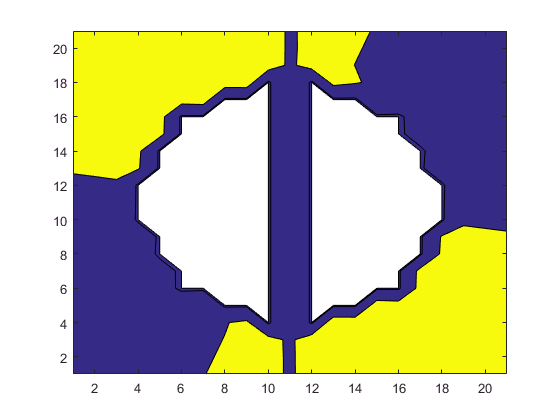

%% functions that show deflection map
showDeflection(F, 'MSA')   